# NLMSフィルタ比較

## ステップサイズによる比較

fleng     = 20;     %タップ数

fsize     = 50000;    %フレームサイズ


ssize = 1;   %ステップサイズ
po = 5;    %次元数

apfilt1 = dsp.AffineProjectionFilter('Length',fleng, 'StepSize',ssize ,'ProjectionOrder', po);

ssize = 0.05;
apfilt2 = dsp.AffineProjectionFilter('Length',fleng, 'StepSize',ssize ,'ProjectionOrder', po);

ssize = 0.001;
apfilt3 = dsp.AffineProjectionFilter('Length',fleng, 'StepSize',ssize ,'ProjectionOrder', po);

ssize = 0.0005;
apfilt4 = dsp.AffineProjectionFilter('Length',fleng, 'StepSize',ssize ,'ProjectionOrder', po);

## ノイズ

Hp = dsp.ColoredNoise('Color','pink','SamplesPerFrame',fsize);
dp = Hp();

Hw = dsp.ColoredNoise('Color','white','SamplesPerFrame',fsize);
dw = Hw();

firfilt = dsp.FIRFilter('Numerator', fir1(10,[.5, .75]));

xp = firfilt(dp);
xw = firfilt(dw);

TS1 = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','0.1');
TS2 = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','0.05');
TS3 = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','0.001');
TS4 = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','0.0005');
TSe = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize, ...
    'ShowLegend',true,'ChannelNames', ...
    {'LMS', 'NLMS', 'AP', 'RLS'},'Title','Err');

## ホワイトノイズ

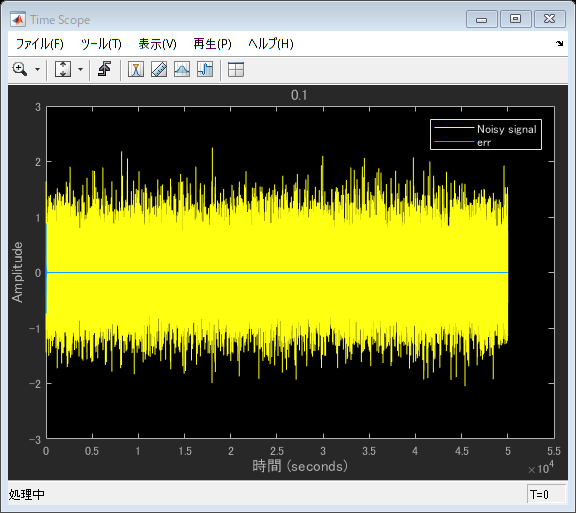

[~,e] = apfilt1(dw,xw);
TS1([xw,e]);

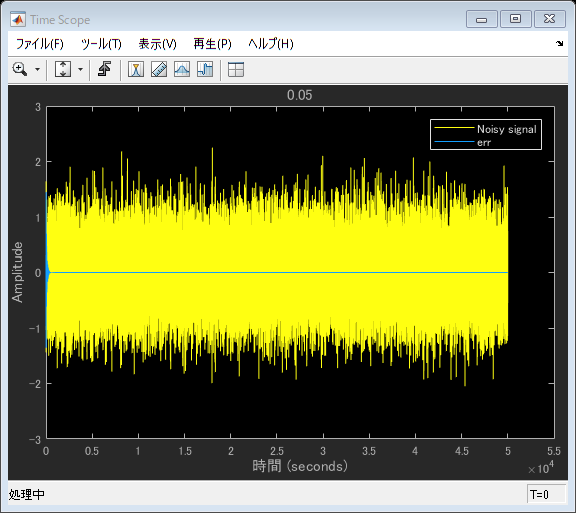

[~,e] = apfilt2(dw,xw);
TS2([xw,e]);

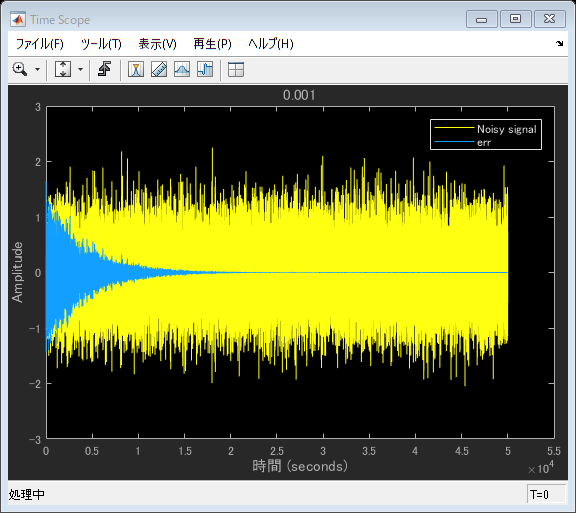

[~,e] = apfilt3(dw,xw);
TS3([xw,e]);

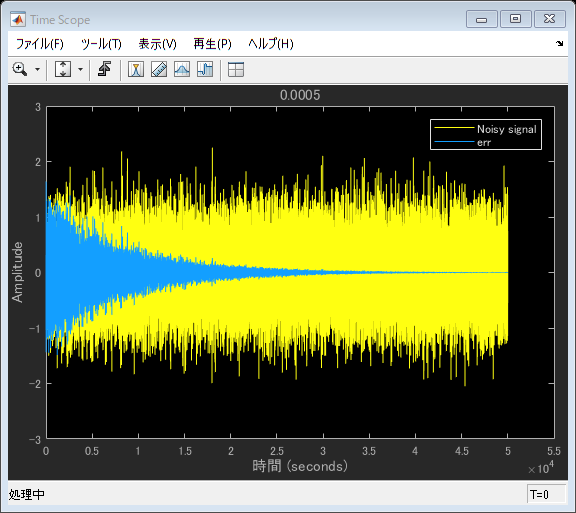

[~,e] = apfilt4(dw,xw);
TS4([xw,e]);

## ピンクノイズ

% [~,e] = apfilt1(dp,xp);
% TS1([xp,e]);
% [~,e] = apfilt2(dp,xp);
% TS2([xp,e]);
% [~,e] = apfilt3(dp,xp);
% TS3([xp,e]);
% [~,e] = apfilt4(dp,xp);
% TS4([xp,e]);
% 
